## Running MidLineFrontal Theta Neurofeedback with Visual Stimulus

In a typical session, you will call the *nfblab_process* with the *runmode* option set to *baseline* to acquire a baseline of about 1 minute. This will allow Neurofeedbacklab to find bad channels, set up the Artifact Subspace Reconstruction filer, run ICA and find bad components. After the baseline run, you run one or more trial runs (*runmode* option set to *trial*)

See *>>nfblab_process('help', true)* for help

Note: NS crashes when connecting via EGI app starts

Possible Protocol: Check Impedance, Exit NS, Start Program, Check Impedance

How to set up multiple trials and BCILab/exec file?

Theta Chan1

## Set Parameters for DenseNet

clear all
% Run nfblab for any headset which has LSL
% ----------------------------------------
addpath(fullfile(pwd, '..','..'));
%Based on Hydrocel GSN 130 Net (256)
nChan = 256; % number of channels
Chan = [26,21,47,2,96,170,126]; %Channel Vector Fpz(COM?), FZ, F7, F8, %Cz (Omitted from acquisition bc system 0's), P7, P8, and Oz *Should be 257 (81, 186?)
sRate = 1000; % sampling rate


## (Optional) Test EEG Connection

From INSTALL.md, Turn on LSL EGI Amp App first

% Turn on Amp via EGIAmpServer-App
lib = lsl_loadlib();
result = nfblab_findlslstream(lib,'EEG','')

result = 1×1 cell array
    {1×1 lsl_streaminfo}


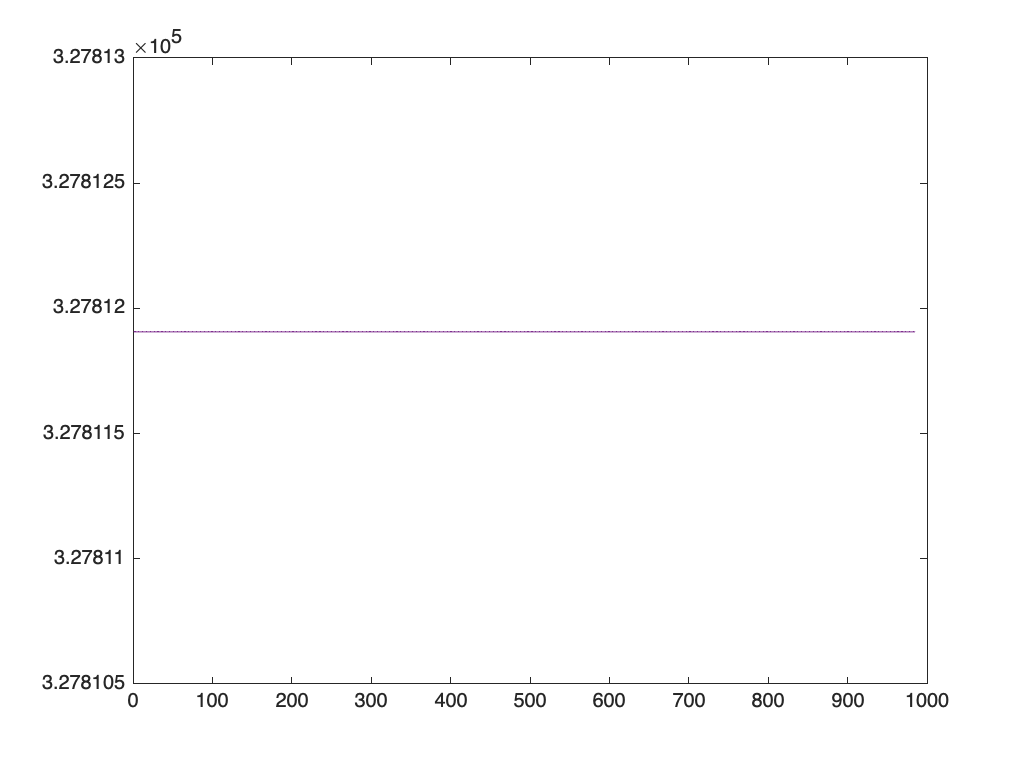

inlet = lsl_inlet(result{1});
pause(1);
[chunk,stamps] = inlet.pull_chunk();
pause(1);
[chunk,stamps] = inlet.pull_chunk();
figure; plot(chunk');

Using the slower MATLAB fallback for setdiff(). Consider setting up a compiler to get much improved BCILAB performance (in some areas).
Looking for a stream with name=EGI NetAmp 0 ...
Opening an inlet...
The number of channels in the steam does not match the number of labeled channel records. Using numbered labels.


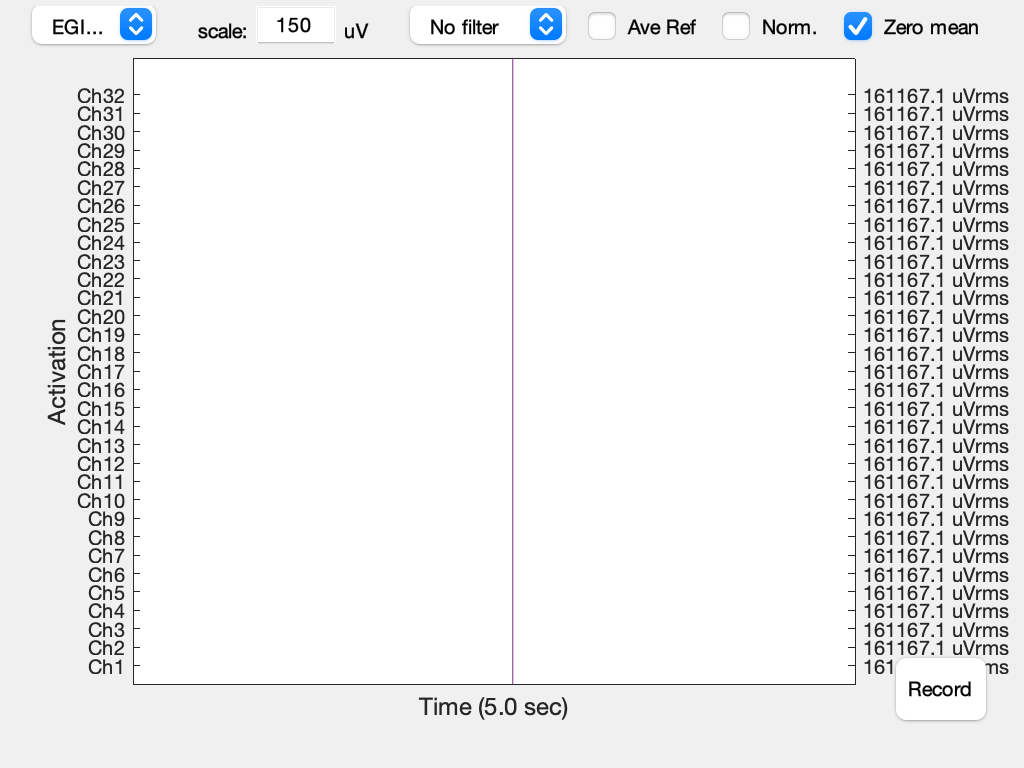

vis_stream()

## Run Baseline

With *nfblab_process.m *with the *runmode* option set to *baseline* to acquire a baseline of about 1 minute

% Run nfblab for MUSE using psychotoolbox for visual feedback
% The psychophysics toolbox need to be installed
% The color of a square changes based on theta power
% -------------------------------------------------------
addpath(fullfile(pwd, '..','..'));

options = { ...
    'chans'                  Chan ...
    'chanmask'               eye(length(Chan)) ...
    'srate'                  250 ...
    'srateHardware'          sRate ...
    'filtFlag'               false ...
    'runmode'               'baseline' ...
    'baselineSessionDuration'   60 ...    
    'pauseSecond'            0.2 ...
    'asrFlag'                false...
    };
nfblab_process(options{:});

Looking up software version (commit hash)
Could not look up software version; Loading software version from file.
**********************
**********************
** NEUROFEEDBACKLAB **
**********************
**********************

Version: fatal: n (git commit)

Type "help nfblab_process" for basic parameter help
Type "nfblab_process('help', true)" for more advanced parameter help
Refer to online documentation and protocols for more information.

HPF has cutoff of 1.0 Hz, transition bandwidth of 0.5 Hz and its order is 3.0
**********************
* session parameters *
**********************
    runmode                  'baseline'
    warnsrate                0
    fileNameAsr              'data_nfblab_2023-10-25_13-48_asr_filter.mat'
    fileNameOut              'data_nfblab_2023-10-25_13-48.mat'
    fileNameRaw              'data_nfblab_2023-10-25_13-48_raw.set'
    TCPIP                    0
    TCPport                  9789


Feedback "Ready" sent to client (if any)
Loading the library...
Resolving an EEG stream...
Opening an inlet...
Now receiving chunked data...
Feedback "Ready" sent to client (if any)
Decoding option runmode: baseline
**********************
* session parameters *
**********************
    runmode                  'baseline'
    warnsrate                0
    fileNameAsr              'data_nfblab_2023-10-25_13-48_asr_filter.mat'
    fileNameOut              'data_nfblab_2023-10-25_13-48.mat'
    fileNameRaw              'data_nfblab_2023-10-25_13-48_raw.set'
    TCPIP                    0
    TCPport                  9789
    pauseSecond              0.2
    baselineSessionDuration  60
    sessionDuration          3600
    help                     0
    checkglobalmsg           
********************
* input parameters *
********************
    lsltype                  'EEG'
    lslname                  
    chans                    [26 21 47 2 96 170 126] 
    srate                    2

Starting new session...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback {"thetaChan1":53.901247664153857,"threshold":"","value":53.901247664153857,"statechange":false,"feedback":0.55} sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback {"thetaChan1":56.2789767601453,"threshold":"","value":56.2789767601453,"statechange":false,"feedback":0.60000000000000009} sent to client (if any)
Feedback {"thetaChan1":55.0651450289779,"threshold":"","value":55.0651450289779,"statechange":false,"feedback":0.65000000000000013} sent to client (if any)
Feedback {"thetaChan1":53.941545614083367,"threshold":"","value":53.941545614083367,"statechange":false,"feedback":0.70000000000000018} sent to client (if 

## Save Filename

trial = 6

trial = 6

filename = sprintf('jo_ws10_25_23_%d.mat',trial);
save(filename)
%consider average reference? req for freq?%%

## Run Single Trial and Save Result

With *nfblab_muse_pscychotoolbox.m*

% Run nfblab for MUSE using psychotoolbox for visual feedback
% The psychophysics toolbox need to be installed
% The color of a square changes based on theta power
% -------------------------------------------------------
addpath(fullfile(pwd, '..','..'));


options = { ...
    'chans'                  Chan ...
    'chanmask'               eye(length(Chan)) ...
    'srate'                  sRate ...
    'srateHardware'          sRate ...
    'filtFlag'               false ...
    'runmode'               'trial' ...
    'sessionDuration'   300 ...  %5min; longer data chunks
    'pauseSecond'            0.2 ...
    'badchanFlag'            false ...
    'icaFlag'                false ...
    'asrFlag'                false ...
    'freqrange'              { [4 8] [8 12] [8 10] [10 12] [18 22] [4 10] [12 15] [20 30] } ... 
    'feedbackMode'           'dynrange' ...
    'funcinit'               'nfblab_feedback_psychootoolbox_init' ...
    'funcfeedback'           'nfblab_feedback_psychootoolbox_process' ...
    'funcend'                'nfblab_feedback_psychootoolbox_end' ...
    };

nfblab_process(options{:});

Looking up software version (commit hash)
Could not look up software version; Loading software version from file.
**********************
**********************
** NEUROFEEDBACKLAB **
**********************
**********************

Version: fatal: n (git commit)

Type "help nfblab_process" for basic parameter help
Type "nfblab_process('help', true)" for more advanced parameter help
Refer to online documentation and protocols for more information.

HPF has cutoff of 1.0 Hz, transition bandwidth of 0.5 Hz and its order is 3.0
**********************
* session parameters *
**********************
    runmode                  'trial'
    warnsrate                0
    fileNameAsr              'data_nfblab_2023-10-25_13-34_asr_filter.mat'
    fileNameOut              'data_nfblab_2023-10-25_13-34.mat'
    fileNameRaw              'data_nfblab_2023-10-25_13-34_raw.set'
    TCPIP                    0
    TCPport                  9789
   

Could not execute feedback function, try running it as a script
PTB-INFO: Retina display. Enabling panel fitter for scaled Retina compatibility mode.


PTB-INFO: This is Psychtoolbox-3 for Apple macOS, under Matlab 64-Bit (Version 3.0.19 - Build date: May  1 2023).
PTB-INFO: OS support status: macOS version 13 Intel is minimally tested and supported.
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: For information about paid support, support memberships and other commercial services, please type
PTB-INFO: 'PsychPaidSupportAndServices'.

PTB-INFO: Installation of the PsychtoolboxKernelDriver is strongly recommended if you care about precise visual
PTB-INFO: onset timestamping or timing. See 'help PsychtoolboxKernelDriver' 

ans = 10

Feedback "Ready" sent to client (if any)
Loading the library...
Resolving an EEG stream...
Opening an inlet...
Now receiving chunked data...
Feedback "Ready" sent to client (if any)
Decoding option runmode: trial
**********************
* session parameters *
**********************
    runmode                  'trial'
    warnsrate                0
    fileNameAsr              'data_nfblab_2023-10-25_13-34_asr_filter.mat'
    fileNameOut              'data_nfblab_2023-10-25_13-34.mat'
    fileNameRaw              'data_nfblab_2023-10-25_13-34_raw.set'
    TCPIP                    0
    TCPport                  9789
    pauseSecond              0.2
    baselineSessionDuration  60
    sessionDuration          300
    help                     0
    checkglobalmsg           
********************
* input parameters *
********************
    lsltype                  'EEG'
    lslname                  
    chans                    [26 21 47 2 96 170 126] 
    srate                    1000
   

Starting new session...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback {"thetaChan1":69.9627852653817,"threshold":"","value":69.9627852653817,"statechange":false,"feedback":0.55} sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback {"thetaChan1":70.44992163005935,"threshold":"","value":70.44992163005935,"statechange":false,"feedback":0.60000000000000009} sent to client (if any)
Feedback {"thetaChan1":69.388423241575239,"threshold":"","value":69.388423241575239,"statechange":false,"feedback":0.65000000000000013} sent to client (if any)
Feedback {"thetaChan1":66.422721118815517,"threshold":"","value":66.422721118815517,"statechange":false,"feedback":0.70000000000000018} sent to client (i

## Save Filename

trial =  5

trial = 5

filename = sprintf('jo_ws10_25_23_%d.mat',trial);
save(filename)